# Experimental methods in psychological sciences

Course for ENS-PSL cognitive science masters program

Part 2: Psychophysics and signal detection theory

This section is written by Tarryn Balsdon

### Introduction

***"It is an unavoidable aspect of psychological experiments that no matter how well instructed, it is the observer who determines how the task is done."*** Galvin et al., 2003

One of the most important factors in designing experimental methods is to ensure the task cannot be done in a way that undermines the hypothesis you are trying to test. This is something well-developed in psychophysics. Even if the subject of investigation (perception) is not of paramount interest to you, the principles are important for all cognitive science.

**Psychophysics** *measures* the relationship between physical stimuli and our psychological experience of them.

These measures are not for the purpose of measurement alone.

Why are we interested in this *measurement*? The measured relationship tells us about the *processes* involved in our psychological experience of physical stimuli. Psychophysical measurement is a powerful tool for gaining insight into: 

- neural processes ("How do neurons change their firing rate as a function of stimulus orientation?")

- cognitive processes ("How do sensitivity and bias contribute to behaviour?")

- task strategies ("How do we optimise performance?")

We focus on classical psychophysics concerning sensory stimuli (mainly vision and audition), but it is important to remember **psychophysical methods generalise to many other domains** (for example, to measure the relationship between monetary value and subjective value, or to measure the perceived evil of different types of crimes - Thurstone, 1927(a)). 

In this part of the course we will examine **the relationship between experimental methods, measurement/analysis, and theory**. The aim is to see how the choice of methods constrains our measures/analyses and therefore what theory/hypotheses can be tested.

This text is written in an interactive MATLAB programming script,** to give you more pictures of the theories and methods**, that you can interact with if you choose to.

The aim is NOT to teach you programming in Matlab, but you can use this to help you understand more about programming if you wish.

The aim is NOT to teach you mathematical equations, but they are there for you if you want to look at them.

I've given some basic description of matlab programming in the "matlab_basics.m" file. There are instructions on the course moodle to help download matlab with the ENS lisence.

To run the script here (in the .mlx version, not the .pdf version), you press the big green "Run" button at the top right. 

If you just want to run one section (faster) you click in that section (anywhere) and press "**Run Section**"

## Section 1. Signal Detection Theory (SDT) and Yes/No vs Forced-choice designs

Detection theory was designed to explain how an observer detects a weak signal in a 'noisy' background. It was originally based on 'statistical decision theory' (describing game strategy; Wald, 1949), and is both an **analytic procedure** for measuring sensitivity and bias in responses, and well as a **normative description** of responding in a noisy environment. The analytic procedure was predicted to be important for studying individual differences and social aspects of perception (Swets, Tanner, & Birdsall, 1961), and indeed, SDT is used in a wide range of experimental settings across many domains of psychological research today. The principles of the normative description are foundational, but less popular today.

### **a. The question of detection**

Humans can detect a single photon of light (Tinsley et al., 2016; Hecht, Shlaer, & Pirenne, 1942). But often a single photon of light goes undetected. Sometimes many photons of light go undetected. Sometimes no photons of light are reported as detected. 

In a **yes/no detection **experiment, the observer is presented with a signal on some trials (signal-present), or otherwise nothing (signal-absent), and they are asked to report 'yes' or 'no' to whether they perceived that the signal was presented on each trial. We calculate proportion correct as the number of trials in which the observer reported 'yes' and the signal was present, plus the number of trials in which the observer reported 'no' and the signal was not present, divided by the total number of trials.

p(correct) = ( sum( 'yes' | signal-present ) + sum( 'no' | signal-absent ) ) / ( sum( signal-present ) + sum( signal-absent ) )

One observer obtains 75% correct. This could be because they correctly reported 'no' on all signal-absent trials, but only reported 'yes' on half the signal-present trials. All signal-present trials used the exact same stimulus, so why doesn't the observer doesn't always give the same response? 75% correct could also be obtained by an observer who correctly detects the signal on all signal-present trials but also responds 'yes' on half the signal-absent trials. What could drive the observer to reoprt something was there when it was not? More realistically, the observer obtains 75% correct because sometime they fail to resport 'yes' when a signal was present, and sometimes they incorrectly report 'yes' when a signal was not present.

How do we explain the variability in detection?

First, a set of theories we now think are wrong.

### **b. Threshold theories**

There are a number of variants of threshold theories (Blackwell, 1953; Luce, 1963; Krantz, 1969), common to all is that there is some threshold that must be surpassed for a signal to be reported as 'present', or otherwise the signal is reported as 'absent', and** 'absent' is a discrete state. **

What is a 'discrete state'? This means that the same psychological experience underlies every report of 'absent'. You would not feel, for example, more certain that Trial 346 was definitely absent while Trial 324 was only probably absent. Some threshold theories also propose that 'present' is also a discrete state (in this case the psychological experience is binary, there is no variability beyond 'present' and 'absent').

What is the threshold? Whatever is strong enough to invoke a 'yes' (could think of this like the 'ignition' in global workspace theory). A key aspect here is that the threshold was not thought of as something we have control over.

What explains the variability? The signal has some probability of surpassing the threshold.

**Version 1: The threshold is variable**

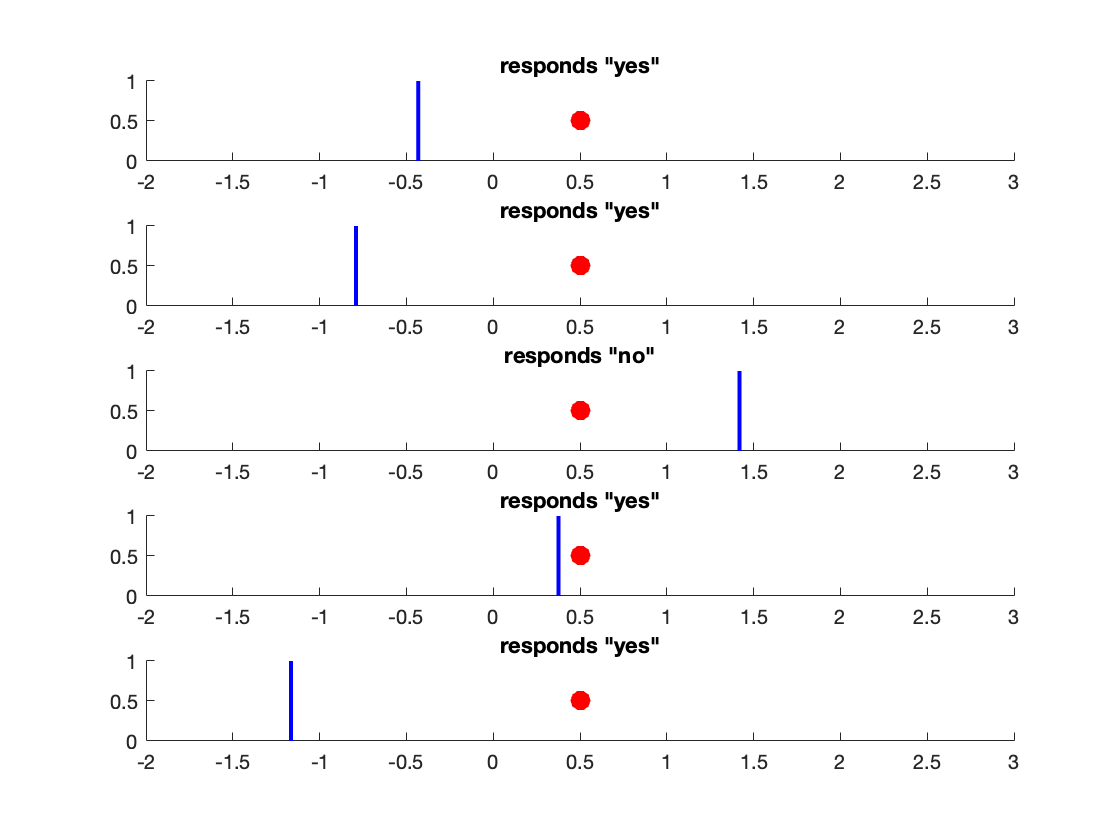


% give the strength of the signal some numerical value
signal_strength = 0.5;

% the threshold varies, let's say it's value is gaussian distributed with
% some mean and variance
threshold_mean = -0.1745;
threshold_sd = 1; % standard deviation (square root of variance)

% let's plot 5 trials
% You can run this section a few times to see more example trials

figure;
for triali = 1:5
    
    % sample value of threshold from a gaussian
    this_threshold = normrnd(threshold_mean,threshold_sd,1,1); 
    
    % plot the signal and the threshold
    subplot(5,1,triali)
    hold on % this means each thing we plot is added on top of the rest
    
    scatter(signal_strength,0.5,100,'r','filled')
    plot([this_threshold,this_threshold],[0,1],'b','LineWidth',2)
    
    % what does the subject respond?
    this_response = signal_strength > this_threshold; 
    % 'yes'/1 if the signal surpasses the threshold

    
    if this_response
        title('responds "yes"')
    else
        title('responds "no"')
    end
    
    axis([-2,3,0,1])
    
end

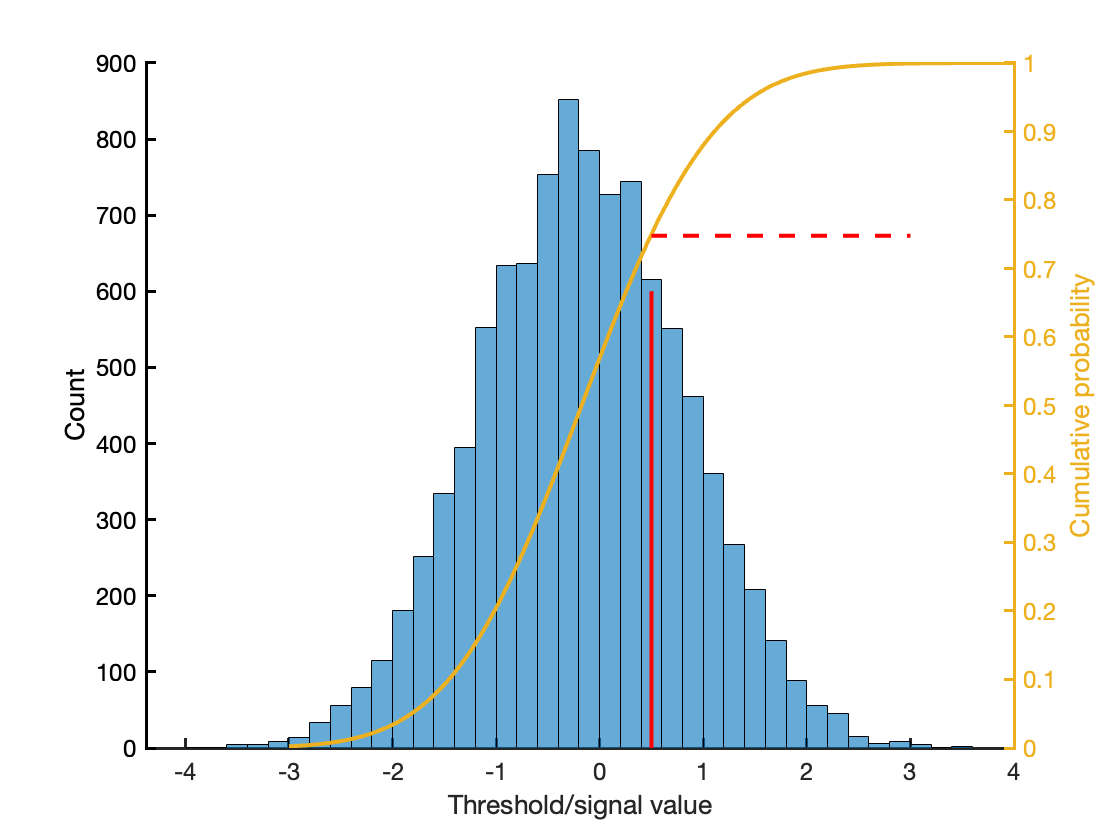


% what happens over many trials?

ntrials = 10000;
thresholds = ( randn(ntrials,1)*threshold_sd ) + threshold_mean; 
% this is another (faster) method of sampling from a gaussian
% the randn function generates samples from the standard normal gaussian,
% we rescale by the standard deviation, then add the mean
% side note: this computationally simple way of transforming gaussians is 
% one of the reasons we like using them

responses = thresholds <= signal_strength ; 
% 'yes'/1 if the signal surpasses the threshold
proportion_correct = mean(responses); 
% the proportion of times the response is 'yes' when the signal was present

% plot
figure;
hold on

histogram(thresholds)
plot([signal_strength,signal_strength],[0,600],'r','LineWidth',2)
ylabel('Count')

% also plot the theoretical description
yyaxis right
xs = linspace(-3,4,301); % possible values of the threshold
ys = normcdf(xs,threshold_mean,threshold_sd);

plot(xs,ys,'LineWidth',2)
plot([0.5,3],[proportion_correct,proportion_correct],'r','LineWidth',2)

ylabel('Cumulative probability')
xlabel('Threshold/signal value')
makeMyPlotPretty

**Version 2: The signal is variable **

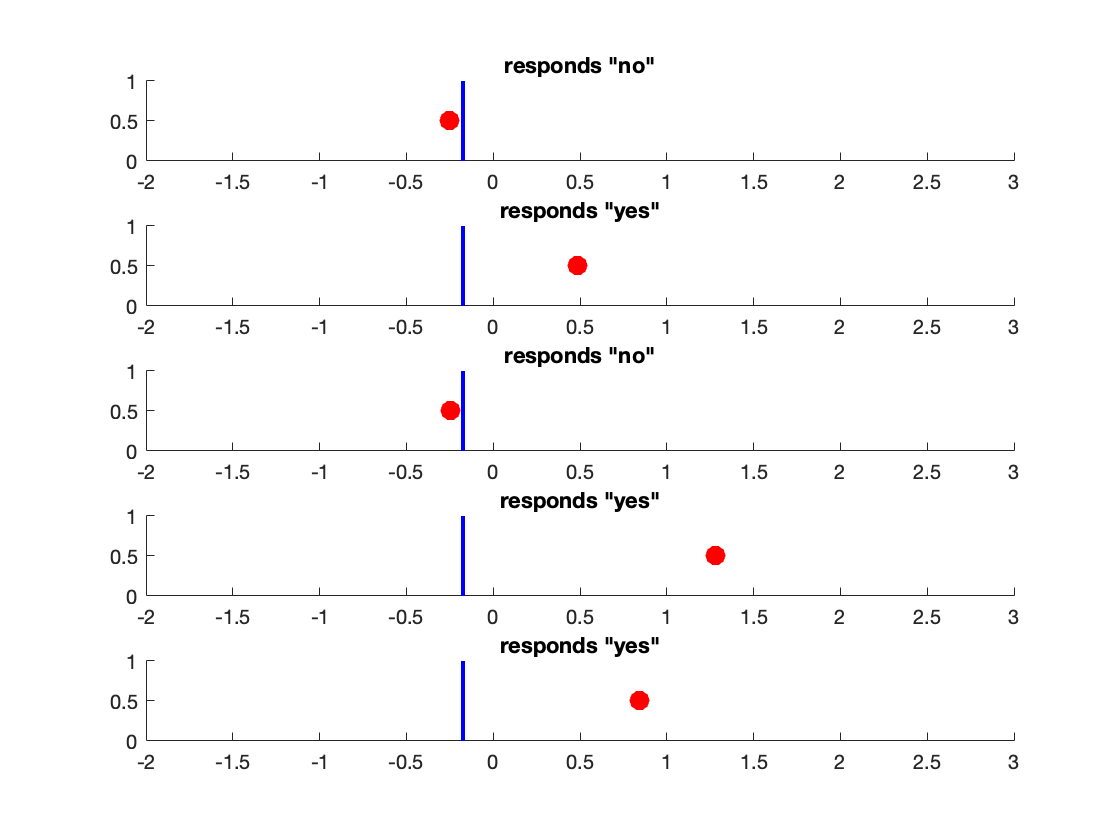


% warning: this is going to look very similar, but pay attention to the
% differences

% give the threshol some numerical value
threshold = -0.1745;

% the signal strength varies, let's say it's value is gaussian distributed with
% some mean and variance
signal_mean = 0.5;
signal_sd = 1; % standard deviation (square root of variance)

% let's plot 5 trials
% You can run this section a few times to see more example trials

figure;
for triali = 1:5
    
    % sample value of threshold from a gaussian
    this_signal = normrnd(signal_mean,signal_sd,1,1); 
    % generate 1 random sample
    
    % plot the signal and the threshold
    subplot(5,1,triali)
    hold on % this means each thing we plot is added on top of the rest
    
    scatter(this_signal,0.5,100,'r','filled')
    plot([threshold,threshold],[0,1],'b','LineWidth',2)
    
    % what does the subject respond?
    this_response = this_signal > threshold; 
    % 'yes'/1 if the signal surpasses the threshold
    
    if this_response
        title('responds "yes"')
    else
        title('responds "no"')
    end
    
    axis([-2,3,0,1])
    
end

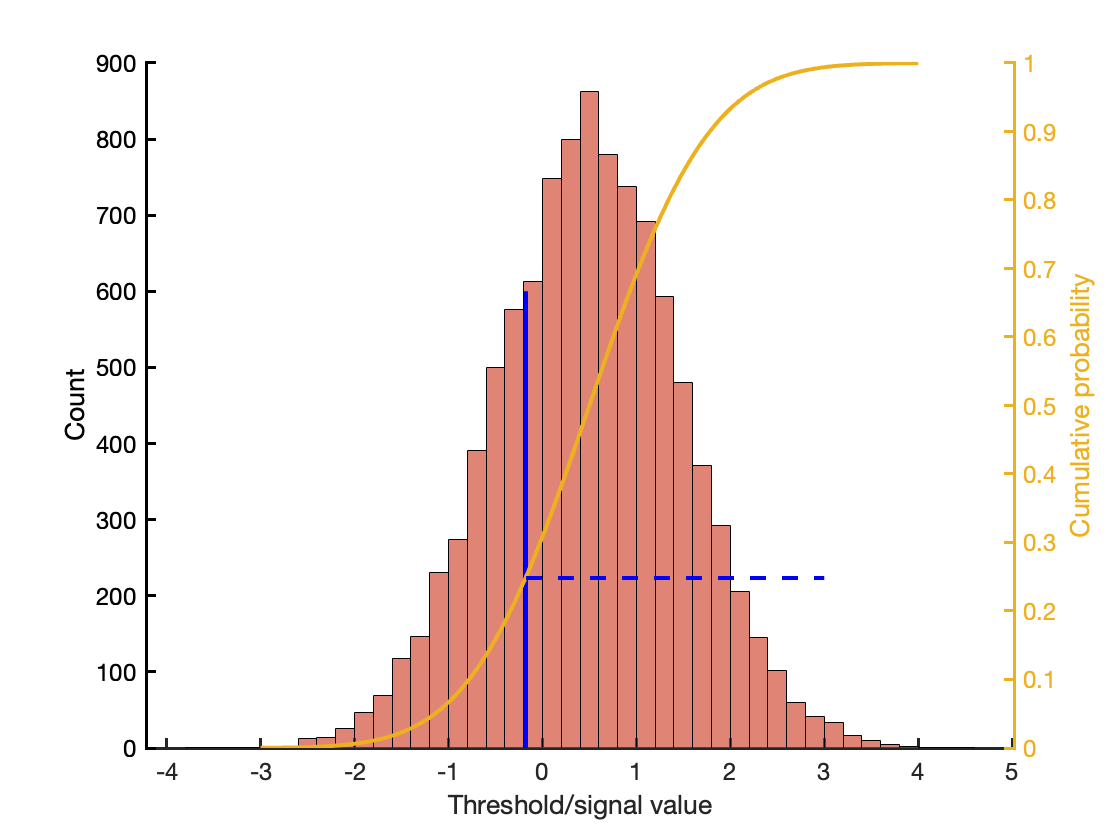


% what happens over many trials?

ntrials = 10000;
signals = ( randn(ntrials,1)*signal_sd ) + signal_mean; % sample signals from a gaussian

responses = signals > threshold ; 
% 'yes'/1 if the signal surpasses the threshold
proportion_correct = mean(responses); 
% the proportion of times the response is 'yes' when the signal was present

% plot
figure;
hold on

histogram(signals,'FaceColor',[0.8,0.2,0.1])
plot([threshold,threshold],[0,600],'b','LineWidth',2)
ylabel('Count')

% also plot the theoretical description
yyaxis right
xs = linspace(-3,4,301); % possible values of the threshold
ys = normcdf(xs,signal_mean,signal_sd);

plot(xs,ys,'LineWidth',2)
plot([threshold,3],[1-proportion_correct,1-proportion_correct],'b','LineWidth',2)

ylabel('Cumulative probability')
xlabel('Threshold/signal value')
makeMyPlotPretty

So both these theories give some explanation of why we have a variable response on signal-present trials.

But what about on signal-absent trials?

Random guessing. 

The theories offer no other explanation of why an observer would report 'yes' when nothing was presented other than that they just might guess sometimes. Maybe the observer thought the signal was presented but they didn't perceive it because they blinked? There is no reason (under threshold theory) why there would be a relationship between these guesses and the probability of reporting 'yes' when the signal is present. This is one of the key things that distinguishes threshold theories from signal detection theory.

Key points

- 'yes' responses on signal-present and signal-absent trials are theoretically independent

- the threshold is not under our control

- 'absent' is a discrete state

### **c. Signal detection theory - a noisy continuum**

The first major conceptual advance of SDT is that it gets rid of the presumption of 'discrete states'. 

Threshold theories propose that anything below threshold is simply 'absent'. A signal-present trial below threshold is experienced as just as absent as a signal-absent trial. 

Under SDT everything has some value on a continuous scale. Some signal-absent trials are psychologically experienced as 'more absent' than other signal-absent trials. AND a signal-absent trial can be experienced as 'more present' than a signal-present trial.

It does this by attributing the variability to a baseline level of 'noise'. This noise is assumed to be gaussian distributed, meaning there is a variable strength on a continuous scale corresponding to the experience of a signal-absent trial. On signal-present trials, the strength of the signal is added to this background of noise, such that it also has a variable strength on the same continuous scale. The distribution describing signal-present trials has a greater mean (and the same standard deviation).

This concept of noise was introduced by Louis Thurstone in 1927(b), who termed it 'discriminal dispersion', and it remains a fundamental concept today.

What is noise? 

Noise can be attributed to variability in neurons firing. A quick demo:

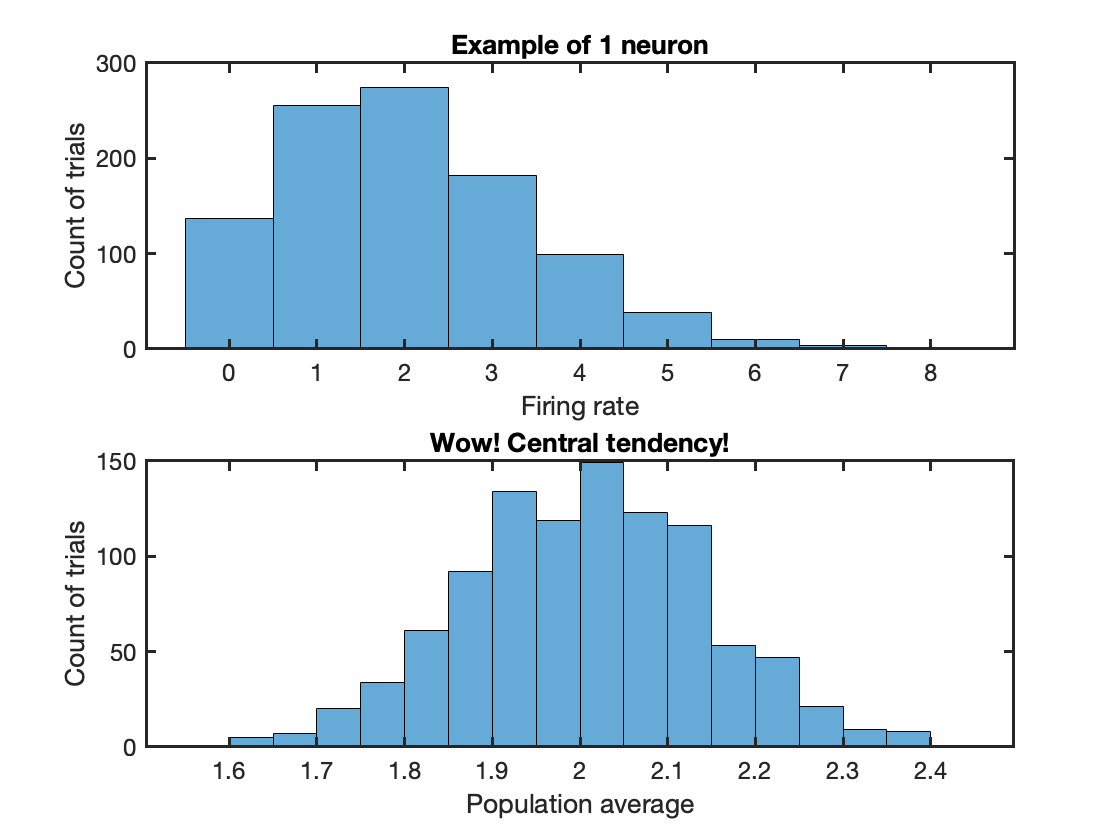


% let's assume you have 100 neurons in V1 who have a baseline firing rate of
% 2 spikes per second (realistically, this is probably much higher
% Niemeyer, & Paradiso, 2017; Albrecht, & Hamilton, 1982)
% Neural firing rates are probabilistic and can be described by a poisson
% distribution
% We sample firing rates from the 100 neurons over 1000 signal-absent trials
firing_rates = poissrnd(2,100,1000); % this function samples a poission distribution

% Let's say we read this out by taking the average firing rate as our
% estimate
est = mean(firing_rates,1); % the average on the first dimension - across neurons

% lets plot this
figure;
subplot(2,1,1)
histogram(firing_rates(1,:))
xlabel('Firing rate')
ylabel('Count of trials')
title('Example of 1 neuron')
makeMyPlotPretty

subplot(2,1,2)
histogram(est)
xlabel('Population average')
ylabel('Count of trials')
title('Wow! Central tendency!')
makeMyPlotPretty

This simple example demonstrates even though individual neuron's firing rates may not be described by a gaussian probability distribution, we can reasonably get a gaussian from the population response. If you are interested in why, the wikipedia page on central tendency is a good place to start.

So, gaussian distributed noise is a neurobiologically plausible assumption for what happens on signal-absent trials.

### d. The criterion

On any trial, the observer experiences something that can be described on a continuous scale, with grater values being more like 'signal-present' and smaller values more like 'signal-absent'. Each trial they have to decide if their experience should be reported as arising from a signal actually being present in the external world. They do this by setting a 'criterion' where anything greater than this criterion is reported as 'yes' a signal was present.

This is the second major conceptual advance of SDT: the response is determined by a criterion/threshold that can be under the observer's strategic control. 

According to statistical decision theory, the observer should place their criterion to maximise their accuracy. This is the normative description part of the theory, that there is some optimal way to behave given the task and the constraints (of the noise). One might also think of this in relation to classic theory of Helmholtz (1867) who described perception as a process of inferring the cause of our sensations. Here, the criterion determines whether we decide our sensation (the psychological experience which can be described as falling on some continuous scale) was caused by a signal-present or signal-absent type of trial.

What do we mean by placing the criterion to maximise accuracy?

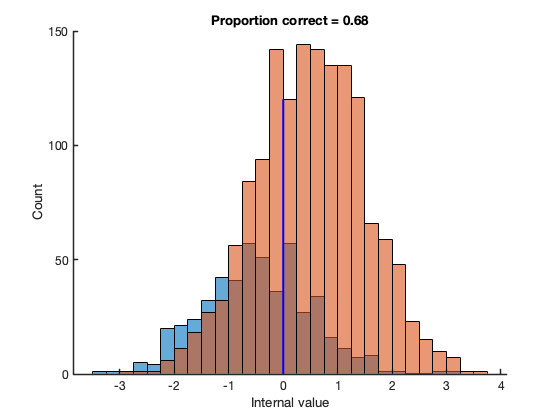


% let's simulate a lot of trials
ntrials = 2000;
psignal = 0.75; % the proportion of signal-present trials

% each trial the observer's experience is affected by some noise
% drawn from a gaussian, with mean and standard deviation:
noise_mean = -0.5;
noise_sd = 1;

noise = (randn(ntrials,1)*noise_sd)+noise_mean;

% the strength of the signal which will be added to the noise 
signal_strength = 1;

% to make things easier, we split into noise trials and signal+noise trials
noise_samps = noise(1:round(ntrials*(1-psignal))); 
% the first half of trials in this case
% I've used the function "round()" to make sure this is an "integer"
% If (1-psignal)*ntrials came to 542.8 (if psignal = 0.7286) then the 
% code would "throw a bug"/break
% because you cant get the 542.8th variable
signal_samps = noise(round(ntrials*(1-psignal))+1:ntrials) + signal_strength; 
% we simply add the signal to the noise

% the decision is based on the criterion, which is placed on some value
% along the continuum
criterion = 0;

noise_yes = noise_samps > criterion ; 
% respond 'yes' when greater than criterion
signal_yes = signal_samps > criterion ; 

% proportion correct: 'no' on signal-absent trials and 'yes' on signal
% present trials

proportion_correct = ( sum(noise_yes == 0) + sum(signal_yes == 1) )/ntrials;

% plot it

figure
hold on
histogram(noise_samps,'BinWidth',0.25)
histogram(signal_samps,'BinWidth',0.25)
plot([criterion,criterion],[0,120],'b','LineWidth',2)
xlabel('Internal value')
ylabel('Count')
title(['Proportion correct = ' num2str(proportion_correct,2)])
makeMyPlotPretty

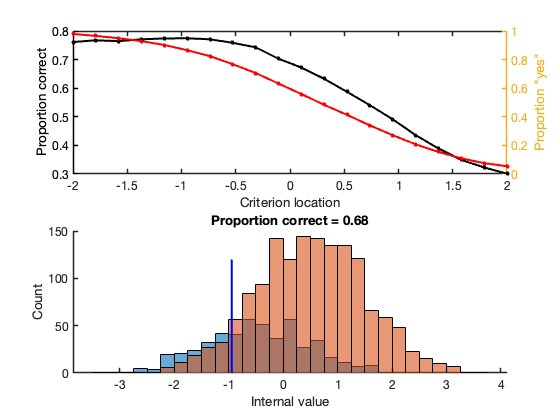


% what happens if we had used a different value of the criterion?

ncriteria = 20;
these_criteria = linspace(-2,2,ncriteria); 
% this gives us 20 equally spaced values from -2 to 2

% we "pre-specify" a matrix of "not a number"/nan that we will fill
these_proportion_correct = nan(size(these_criteria));
these_proportion_yes = nan(size(these_criteria)); 
% also calculate proportion of 'yes' responses

% calculate proportion correct for each criterion
for ci = 1:ncriteria
    
    these_proportion_correct(ci) = ( sum(noise_samps <= these_criteria(ci)) + ... % the noise correctly reported as "no"
        sum(signal_samps > these_criteria(ci)) )... % the signal correctly reported as "yes"
        /ntrials; % divided by the total number
    
    these_proportion_yes(ci) = ( sum(noise_samps > these_criteria(ci)) + ...
        sum(signal_samps > these_criteria(ci)) ) /ntrials;
end

% in the above, I told matlab I am going to break one line of code over
% multiple lines using "..." this is just for read-ability, I could have
% put it all on one line

% plot the results
figure
subplot(2,1,1)
plot(these_criteria,these_proportion_correct,'k','LineWidth',2)
hold on
scatter(these_criteria,these_proportion_correct,20,'k','filled')
ylabel('Proportion correct')

yyaxis right

plot(these_criteria,these_proportion_yes,'r','LineWidth',2)
scatter(these_criteria,these_proportion_yes,20,'r','filled')
ylabel('Proportion "yes"')
xlabel('Criterion location')
makeMyPlotPretty


% which criterion maximises accuracy?

[maximum_accuracy,which_criterion] = max(these_proportion_correct); 
% here the second output from the max function tells me which one in order
best_criterion = these_criteria(which_criterion); % to get the value

subplot(2,1,2)
hold on
histogram(noise_samps,'BinWidth',0.25)
histogram(signal_samps,'BinWidth',0.25)
plot([best_criterion,best_criterion],[0,120],'b','LineWidth',2)
xlabel('Internal value')
ylabel('Count')
title(['Proportion correct = ' num2str(proportion_correct,2)])
makeMyPlotPretty

You should hopefully see that the best criterion is about 0 (this will vary a little because of variability in our samples). 

For tasks where the experimenter presents 50% signal-present and 50% signal-absent, the optimal location of the criterion is mid-way between the distributions of noise and signal+noise. Here the mean of noise is -0.5, the mean of signal+noise is 0.5, so the optimal location is 0.

**TAKE AWAY 1:** An observer who is affected by the same underlying noise can achieve worse proportion correct because they don't put their criterion in the correct location

**TASK 1:** Modify the variable psignal (for example, psignal = 0.6) and run the code again. Try a few.

**TAKE AWAY 2:** The optimal placement of the criterion is [always mid-way between the means of the distributions] / [depends on the task designed by the experimenter] (delete one)

If the participant can set their criterion at the optimal location, they can maximise their accuracy. Accuracy is dependent on both the *sensitivity* of the observer (separation of noise and signal+noise distributions) as well as their ability to optimally place their criterion.

It has been shown that people do adjust their criterion:

a. when performing a task where the *signal-present trials are more likely*, people place their criterion to be more *liberal* in responding 'yes'

b. when performing a task where the *signal-absent trials are more likely*, people place their criterion to be more *conservative* in responding 'yes'

Is this optimal according to the simulation you perfomed in TASK 1?

People also make similar adjustments when one response is more rewarded (place the criterion to be more liberal in responding 'yes' when a corrrect 'yes' response is rewarded more than 'no'). This motivated Swets, Tanner & Birdsall (1961) to suggest that the criterion was under voluntary control by the observer (it reflects a motivation to obtain a reward). This is also one reason why Swets, Tanner, & Birdsall (1961) suggest this theory could be useful for studying individual differences and social influences on perception. 

Finally, this suggests that Key point 2 of Threshold theory (that the threshold is not under our control) is false.

However, criterion placement is not the only factor contributing to proportion correct.

### e. Sensitivity

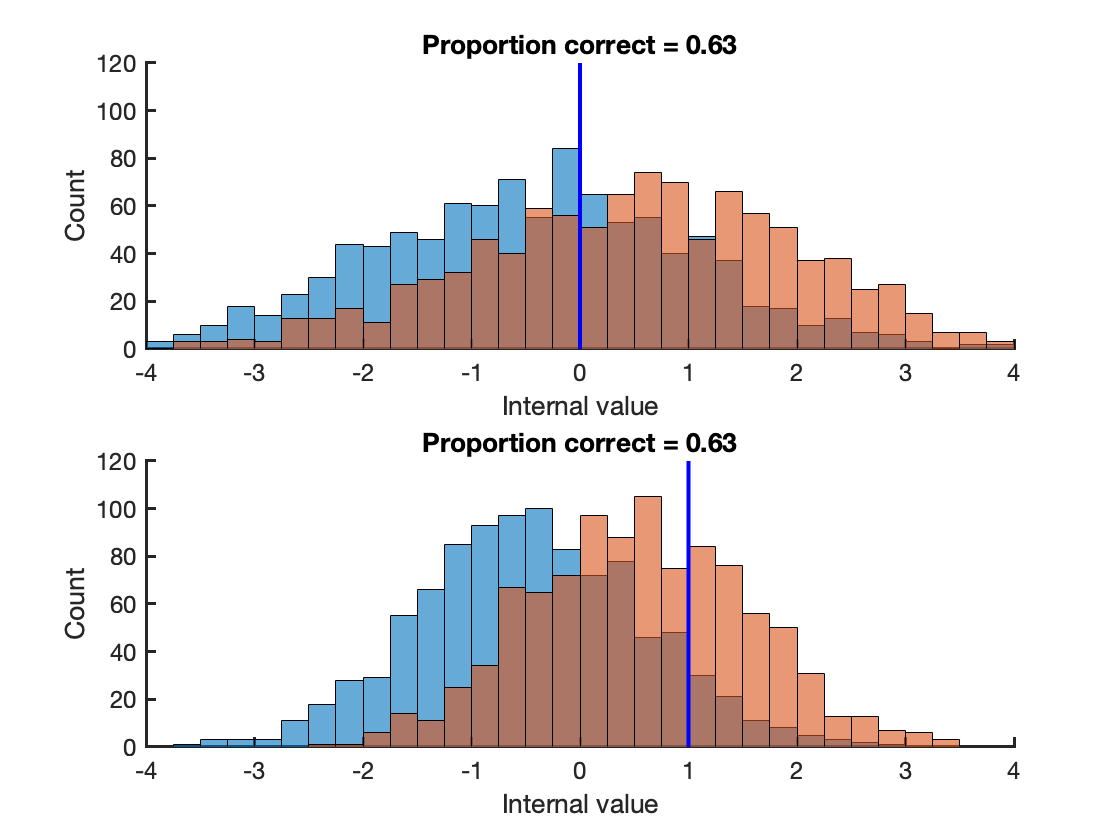


% A second observer experiences more noise

ntrials = 2000;
psignal = 0.5; % the proportion of signal-present trials

% each trial the observer's experience is affected by some noise
% drawn from a gaussian, with mean and standard deviation:
noise_mean2 = -0.5;
noise_sd2 = 1.5;

noise2 = (randn(ntrials,1)*noise_sd2)+noise_mean2;

% the strength of the signal which will be added to the noise 
signal_strength = 1;

% to make things easier, we split into noise trials and signal+noise trials
noise_samps2 = noise2(1:round(ntrials*(1-psignal))); 
% the first half of trials in this case
signal_samps2 = noise2(round(ntrials*(1-psignal))+1:ntrials) + signal_strength; 
% we simply add the signal to the noise

% the decision is based on the criterion, which is placed on some value
% along the continuum
criterion2 = 0;

% proportion correct: 'no' on signal-absent trials and 'yes' on signal
% present trials

proportion_correct2 = (sum(noise_samps2 <= criterion2)+sum(signal_samps2 > criterion2))...
    / ntrials;

% plot

figure
subplot(2,1,1)
hold on
histogram(noise_samps2,'BinWidth',0.25)
histogram(signal_samps2,'BinWidth',0.25)
plot([criterion2,criterion2],[0,120],'b','LineWidth',2)
axis([-4,4,0,120])
xlabel('Internal value')
ylabel('Count')
title(['Proportion correct = ' num2str(proportion_correct2,2)])
makeMyPlotPretty

% compare with our first observer, but one with a biased criterion

% each trial the observer's experience is affected by some noise
% drawn from a gaussian, with mean and standard deviation:
noise_mean = -0.5;
noise_sd = 1;

noise = (randn(ntrials,1)*noise_sd)+noise_mean;

% to make things easier, we split into noise trials and signal+noise trials
noise_samps = noise(1:round(ntrials*(1-psignal))); 
% the first half of trials in this case
signal_samps = noise(round(ntrials*(1-psignal))+1:ntrials) + signal_strength; 
% we simply add the signal to the noise

% the decision is based on the criterion, which is placed on some value
% along the continuum
criterion = 1;

% proportion correct: 'no' on signal-absent trials and 'yes' on signal
% present trials

proportion_correct = (sum(noise_samps <= criterion)+sum(signal_samps > criterion))...
    / ntrials;

% plot it

subplot(2,1,2)
hold on
histogram(noise_samps,'BinWidth',0.25)
histogram(signal_samps,'BinWidth',0.25)
plot([criterion,criterion],[0,120],'b','LineWidth',2)
axis([-4,4,0,120])
xlabel('Internal value')
ylabel('Count')
title(['Proportion correct = ' num2str(proportion_correct,2)])
makeMyPlotPretty

These observers obtain similar proportion correct. 

The observer plotted on top uses an optimal criterion, but they experience more noise, meaning that signal-present trials are experienced very similarly to signal-absent trials, they can't tell them apart (they have trouble genuinely detecting the signal).

The observer plotted on the bottom experiences less noise, meaning that signal-present trials are often experienced with greater internal values than signal-absent trials (they detect the signal just fine). But they do badly at the task because they placed their criterion too conservatively.

Based on proportion correct, the observers are about the same. But one observer genuinely doesn't detect the signal well, while the other is unwilling to report a weak signal as being signal-present. 

So there are two distinct reasons why someone could do poorly at the task: they could be genuinely bad at detecting the signal, or they could be biased in what they report as a signal.

Proportion correct alone can't distinguish these two observers. This is why SDT remains a popular analytical procedure: it suggests an analysis to distinguish these two factors contributing to performance.

Rather than calculating proportion correct, SDT relies on the proportion of "yes" responses, for signal-present and signal-absent trials separately:

A "yes" on a signal-present trial is called a **hit **(a "no" is called a miss)

A "yes" on a signal-absent trial is called a **false alarm **(a "no" is called a correct rejection).

The proportions of "yes" responses are called the hit-rate and false-alarm-rate respectively

The analytic procedure of SDT calsulates *sensitivity* as:

d-prime = norminv( hit_rate ) - norminv( false_alarm_rate )

And the criterion as:

c = ( norminv( hit_rate ) + norminv( false_alarm_rate ) ) / 2

where bias is a value of c different from 0

norminv is the inverse of the cumulative normal gaussian (the normal gaussian has mean = 0 and standard deviation = 1). It tells us at what point on the x-axis (internal value) the cumulative count of ordered values reaches that proportion... it's easier to demonstrate...

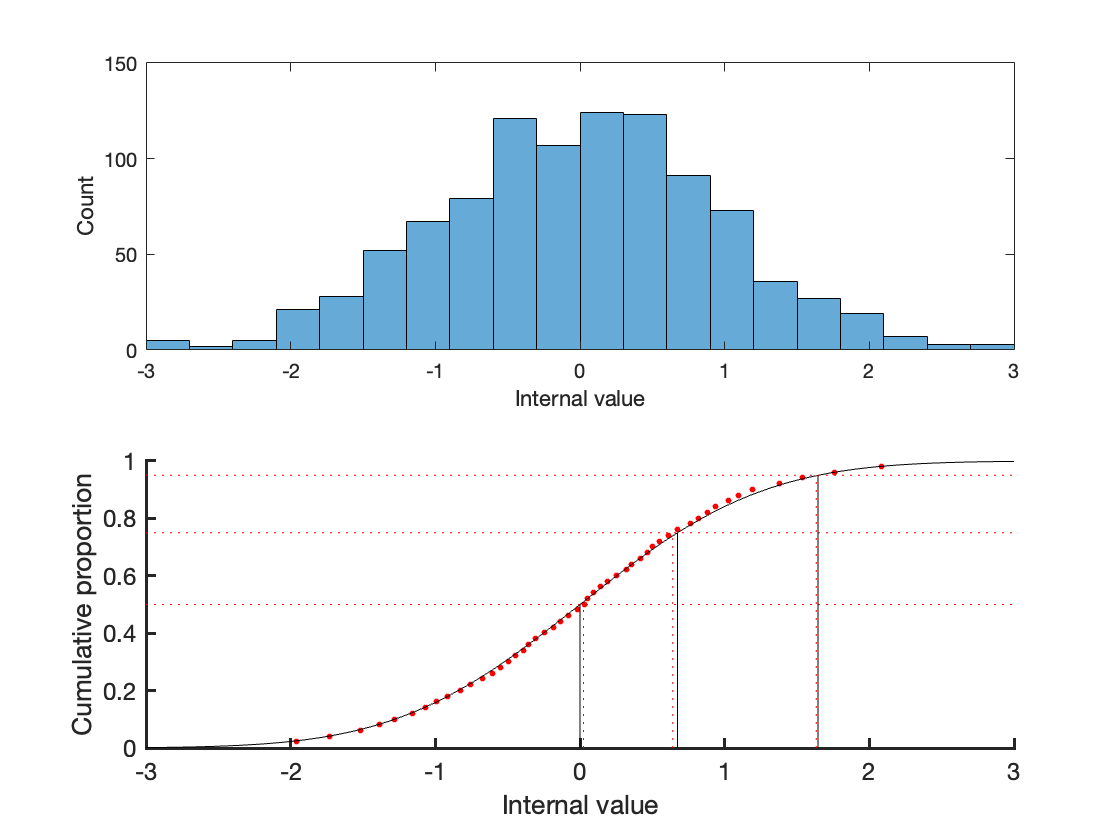


% the normal gaussian
ng_mean = 0;
ng_sd = 1;

% grab lots of samples
nsamples = 1000;
samples = normrnd(ng_mean,ng_sd,nsamples,1); 
% if I had used randn as above, you can see why specifying the 
% mean and sd is a waste of time here
%samples = ( randn(nsamples,1)*ng_sd ) + ng_mean;

% plot the histogram
figure
subplot(2,1,1)
histogram(samples)
axis([-3,3,0,150])
xlabel('Internal value')
ylabel('Count')

% to plot the cumulative distribution:
% sort the samples in ascending order
samples_sorted = sort(samples);

subplot(2,1,2)
hold on
scatter(samples_sorted(1:20:nsamples),(1:20:nsamples)./nsamples,10,'r','filled') 
% just every 100th value
% plot on top the theoretical cumulative
xs = linspace(-3,3,100);
ys = normcdf(xs,ng_mean,ng_sd); % this is the function for the cumulative normal
plot(xs,ys,'k')
xlabel('Internal value')
ylabel('Cumulative proportion')
axis([-3,3,0,1])
makeMyPlotPretty

% also plot some examples
a = norminv(0.5);
b = norminv(0.75);
c = norminv(0.95);

% norminv is supposed to give us the value on the x-axis that corresponds
% to the proportion.

% the equivalent from the samples
a_sampled = samples_sorted(nsamples*0.5);
b_sampled = samples_sorted(nsamples*0.75); 
% this is the sample that corresponds to 75% of the sorted values
c_sampled = samples_sorted(nsamples*0.95);

% plot on top
plot([-3,3],[0.5,0.5],'r:')
plot([-3,3],[0.75,0.75],'r:')
plot([-3,3],[0.95,0.95],'r:')
plot([a,a],[0,0.5],'k')
plot([a_sampled,a_sampled],[0,0.5],'r:')
plot([b,b],[0,0.75],'k')
plot([b_sampled,b_sampled],[0,0.75],'r:')
plot([c,c],[0,0.95],'k')
plot([c_sampled,c_sampled],[0,0.95],'r:')
makeMyPlotPretty

You should see that the sample in the position 75% of total ordered samples is approximately equal to norminv(0.75)

What is the value of norminv(0.95)?

This is the same value as the cut off for an alpha level of 0.05 for a one-tailed z-test!

The same distribution is used for the standard z-test in statistics

OK, back to d-prime

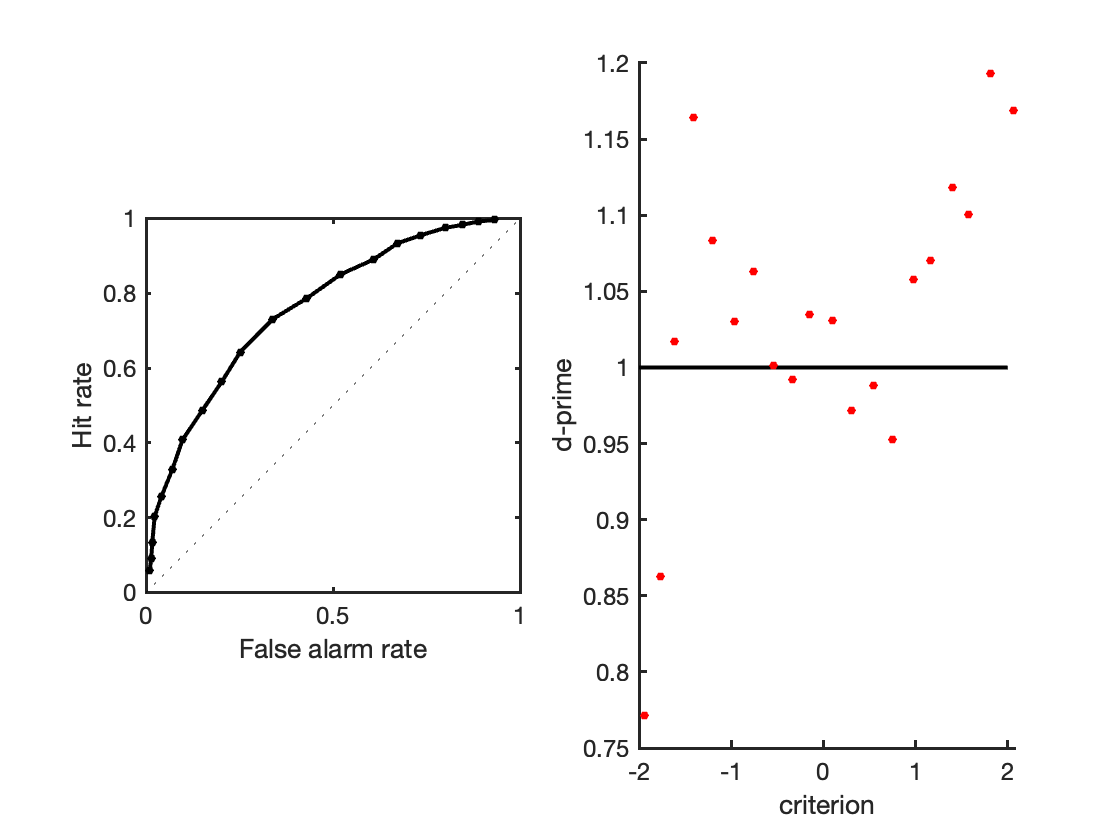


% For observer 1, calculate the hit-rate and false-alarm-rate at each of
% the criteria
% Use this to calculate d-prime and c

% back to the distributions of observer 1
ntrials = 2000;
psignal = 0.5; % the proportion of signal-present trials

signal_strength = 1;

noise_mean = -0.5;
noise_sd = 1;

noise = (randn(ntrials,1)*noise_sd)+noise_mean;

noise_samps = noise(1:round(ntrials*(1-psignal))); 
% the first half of trials in this case
signal_samps = noise(round(ntrials*(1-psignal))+1:ntrials) + signal_strength; 
% we simply add the signal to the noise

ncriteria = 20;
these_criteria = linspace(-2,2,ncriteria); 
% this gives us 20 equally spaced values from -2 to 2

% pre-specify the variables
hit_rates = nan(ncriteria,1);
fa_rates = nan(ncriteria,1);

for ci = 1:ncriteria
    
    hit_rates(ci) = mean(signal_samps > these_criteria(ci)); 
    % here "mean" gives us the proportion, because inside the 
    % bracket will be an array of 0s and 1s
    fa_rates(ci) = mean(noise_samps > these_criteria(ci));
end

% calculate d-prime and criteria
d_primes = norminv(hit_rates) - norminv(fa_rates);
criteria_calculated = 0.5 * ( norminv(hit_rates) + norminv(fa_rates) );

% plot
figure
subplot(1,2,1)
plot(fa_rates,hit_rates,'k','LineWidth',2)
hold on
scatter(fa_rates,hit_rates,20,'k','filled')
plot([0,1],[0,1],'k:')
xlabel('False alarm rate')
ylabel('Hit rate')
axis square
makeMyPlotPretty

subplot(1,2,2)
hold on
% the theoretical result
plot(these_criteria,ones(ncriteria,1)*(signal_strength/noise_sd),'k','LineWidth',2)
% our calculations from 2000 trials
scatter(criteria_calculated,d_primes,20,'r','filled')

xlabel('criterion')
ylabel('d-prime')
makeMyPlotPretty

The figure on the left is called a "receiver operating curve" or ROC or commonly "ROC curve".

What it shows is that there is a systematic relationship between the probability of responding "yes" on signal-absent trials and the probability of reporting "yes" on signal-present trials, contrary to key point 1 of Threshold Theory (for Threshold Theory there is no reason why someone should increase guessing "yes" while experiencing a discrete absent state, and the probability of experiencing a signal-present).

This relationship was shown using the yes/no task with different manipulations (the proportion of signal-present trials, and the reward for correct "yes" vs "no" responses). This was taken as evidence against Threshold Theory.

**TASK 2: **Try changing the value of noise_sd, and (separately) the value of signal_strength and re-running the code

**TAKE-AWAY 3:** d-prime [does]/[does not] distinguish an observer with more noise from an observer with weaker signal (delete one)

**TASK 3:** Try changing the the number of trials (halve it, and double it).

d-prime measures the ratio of signal to noise. The theoretical equation is:

d-prime = ( signal_mean - noise_mean ) / noise_sd 

(The distance of the signal distribution from the noise distribution in units of standard devation)

The equation we use to calculate d-prime is a simple way of getting to this measure from the data.

You should see that our estimate of d-prime from 2000 trials is relatively poor when the criterion becomes more biased (away from 0), and it gets worse with fewer trials. In normal experiments we might have only 200 trials, and we don't know how biased our observers will be.

One thing that can be used to improve our measure of sensitivity is to use responses across the ROC. This is done by manipulating criterion placement in different conditions, or using a rating-response (see below). The d-prime equation above is then used to calculate d-prime across the full ROC curve using a fitting method (I won't go into details).

If we are interested in getting a good measure of sensitivity, we should get rid of the bias problem.

Use a foced-choice task!

### f. Minimising bias with forced-choice designs

The **2AFC task **presents the observer with two "intervals" one signal-present, and one signal-absent, the observer decides which interval is signal-present

To do this, they don't need to decide how much internal value should qualify as a "yes" response (set a criterion), they simply respond which interval they experienced a stronger internal value.

NOTE: the 2AFC task is not necessarily bias-free. An observer could have a preference for a particular response (for example, one response could be made with their right hand, and they simply prefer to use their right hand). But, a preference for a particular response no longer corresponds to reporting a particular experience (because signal-present and signal-absent should be equally likely to correspond to each response).

Let's visualise this.

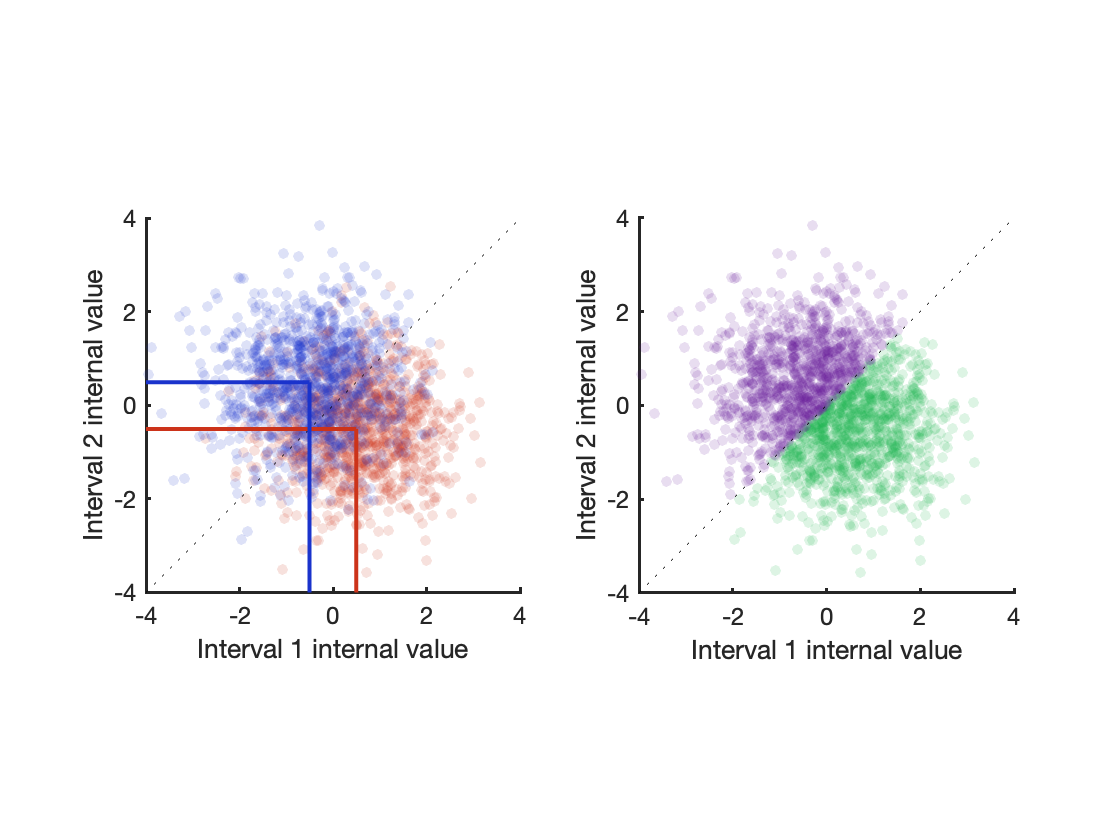


% every trial the observer is presented with two intervals (both are
% affected by noise, the noise is independent across the two intervals)
ntrials = 2000;

noise_mean = -0.5;
noise_sd = 1;

interval1_samps = ( randn(ntrials,1)*noise_sd ) + noise_mean;
interval2_samps = ( randn(ntrials,1)*noise_sd ) + noise_mean;

% half the time, interval 1 contains the signal, the other half, interval 2
% contains the signal
signal_strength = 1;

interval1_samps(1:(ntrials/2)) = interval1_samps(1:(ntrials/2)) + signal_strength;
interval2_samps((ntrials/2)+1:ntrials) = interval2_samps((ntrials/2)+1:ntrials) ...
    + signal_strength;

% obviously in a real experiment these would be in random order

% the participant responds 1 if interval1 is stronger than interval 2
responses = interval1_samps > interval2_samps ;

% plot
figure;
subplot(1,2,1)
hold on
% different colours for signal present in interval 1 vs 2
s1 = [0.8,0.2,0.1]; % redish for interval 1
s2 = [0.1,0.2,0.8]; % blueish for interval 2

scatter(interval1_samps(1:(ntrials/2)),interval2_samps(1:(ntrials/2)),...
    30,s1,'filled','MarkerFaceAlpha',0.15)
scatter(interval1_samps((ntrials/2)+1:ntrials),interval2_samps((ntrials/2)+1:ntrials),...
    30,s2,'filled','MarkerFaceAlpha',0.15)
plot([-4,4],[-4,4],'k:')
plot([-4,0.5],[-0.5,-0.5],'Color',s1,'LineWidth',2)
plot([0.5,0.5],[-4,-0.5],'Color',s1,'LineWidth',2)
plot([-4,-0.5],[0.5,0.5],'Color',s2,'LineWidth',2)
plot([-0.5,-0.5],[-4,0.5],'Color',s2,'LineWidth',2)
axis([-4,4,-4,4])
axis square
xlabel('Interval 1 internal value')
ylabel('Interval 2 internal value')
makeMyPlotPretty

subplot(1,2,2)
hold on
% different colours for the different responses
r1 = [0.1,0.7,0.3]; % greeny for interval 1
r2 = [0.4,0.1,0.6]; % purply for interval 2

scatter(interval1_samps(responses==1),interval2_samps(responses==1),30,...
    r1,'filled','MarkerFaceAlpha',0.15)
scatter(interval1_samps(responses==0),interval2_samps(responses==0),30,...
    r2,'filled','MarkerFaceAlpha',0.15)
plot([-4,4],[-4,4],'k:')
axis([-4,4,-4,4])
axis square
xlabel('Interval 1 internal value')
ylabel('Interval 2 internal value')
makeMyPlotPretty

The distributions are termed 2D gaussians. You should see the means on each axis correspond to the means of the noise/signal+noise depending on which contains the signal


% calculate proportion correct

proportion_correct = ( sum(responses(1:(ntrials/2))==1) + ...
    sum(responses((ntrials/2)+1:ntrials)==0) ) / ntrials;

% let's pretend the observer was presented with the same evidence, but this
% time in a yes/no task
% they have an ideal criterion (at 0)
responses_yn = [interval1_samps > 0; interval2_samps > 0]; 
% this concatenates yes/no responses for interval1 
% samples followed by interval2 samples
% code the correct response, because now things have an annoying order
correct_yn = [ones(ntrials/2,1);zeros(ntrials/2,1);zeros(ntrials/2,1);ones(ntrials/2,1)];

proportion_correct_yn = mean(responses_yn == correct_yn);

hit_rate_yn = mean(responses_yn(correct_yn==1)); % proportion yes on signal present
fa_rate_yn = mean(responses_yn(correct_yn==0)); % proportion no on signal absent

dprime_yn = norminv(hit_rate_yn) - norminv(fa_rate_yn);

% a similar equation for the forced choice
hit_rate_2afc = mean(responses(1:(ntrials/2)) == 1); 
% responding 1 when the signal was in interval 1
fa_rate_2afc = mean(responses((ntrials/2)+1:ntrials) == 1); 
% responding 1 when the signal was in interval 2

dprime_2AFC_uncorrected = norminv(hit_rate_2afc) - norminv(fa_rate_2afc);

dprime_2AFC_corrected = dprime_2AFC_uncorrected * (1/sqrt(2));

% we can also use a short-cut for calculating dprime in the 2AFC task:
dprime_2AFC = sqrt(2) * norminv(proportion_correct);

You should see that proportion correct is actually higher in the 2AFC task compared to the Yes/No task. This is because the observer gets two presentations with uncorrelated noise. The correction for d-prime to be equivalent to the yes/no d-prime uses a sqrt(2) correction, can you see from the figure on the left above why? (hint: Pythagoras)

Let's pretend that Threshold Theory were true. Key point 3 is that absent is a discrete state. In this case, the 2AFC task itself doesn't make much sense: either the signal surpasses the threshold and the observer responds as they would in a yes/no task, or the signal does not surpass the threshold and the observer has to guess between two equally absent experiences.

What happens when we compare performance across these two tasks under Threshold Theory

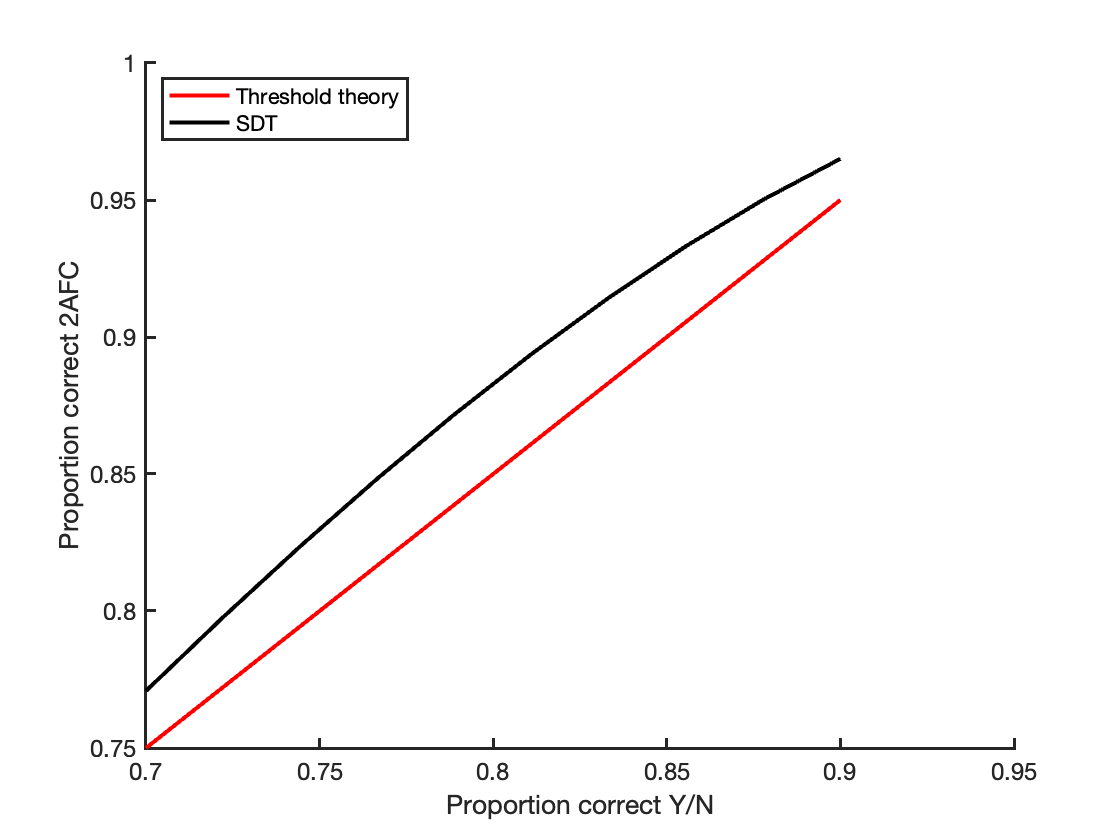


% the quick and dirty way...
p_yes_signalpresent = linspace(0.5,0.9,10); 
% for proportions yes ranging from 0.5 to 0.9
p_yes_signalabsent = 0.1; 
% the observer just guesses 'yes' on a certain proportion of 
% signal-absent trials for no specified reason...

tt_proportion_correct_yn = (p_yes_signalpresent*0.5) + ((1 - p_yes_signalabsent)*0.5);

% an example
% in the 2AFC task, they still perceive the signal-present as present 60%
% of the time
% on the other 40% of trials, they get 2 equally absent intervals and
% guess, giving 50% correct

tt_proportion_correct_2afc = p_yes_signalpresent + (0.5*(1 - p_yes_signalpresent));

figure
hold on
plot(tt_proportion_correct_yn,tt_proportion_correct_2afc,'r','LineWidth',2)
xlabel('Proportion correct Y/N')
ylabel('Proportion correct 2AFC')

% the theoretical relationship (for an unbiased observer) under SDT
pc_yn = linspace(0.7,0.9,10);
pc_2afc = normcdf(2*norminv(pc_yn)/sqrt(2)); 
% unbiased yes/no proportion correct can be used to calculate dprime =
% 2*norminv(pc_yn)
% then proportion correct in the 2AFC task is pc_2afc =
% normcdf(dprime/sqrt(2)
plot(pc_yn,pc_2afc,'k','LineWidth',2)
legend('Threshold theory','SDT','location','northwest')
makeMyPlotPretty

Threshold Theory cannot predict how much performance increases in the 2AFC task, because the 'discrete absent state' suggests a certain proportion of trials must be guesses. Measured performance across 2AFC vs Yes/No tasks can also be used to discredit Threshold Theory

**TAKE-AWAY 4:** Observers have a continuous experience, where one signal-absent trial is experienced differently from another signal-absent trial. 

### g. The rating-response

More evidence for this continuity of experience also came from experiments using a rating-response. 

The rating-response can be used in yes/no or 2AFC tasks. Instead of asking for a binary response (yes/no or interval1/interval2), the observer is asked for a rating corresponding to their experience (e.g. 1 = very much no signal, 2 = not really a signal, 3 = maybe a signal, 4 = very much a signal). Of note, these ratings were originally intended to be a rating of the experience, not a metacognitive confidence rating (which evaluates the likelihood the decision is correct), these are theoretically different ratings (though often there is limited practical difference; for more on this, Galvin et al., 2003 gives a very detailed explanation). Essentially, the observer places multiple criteria on the internal value.

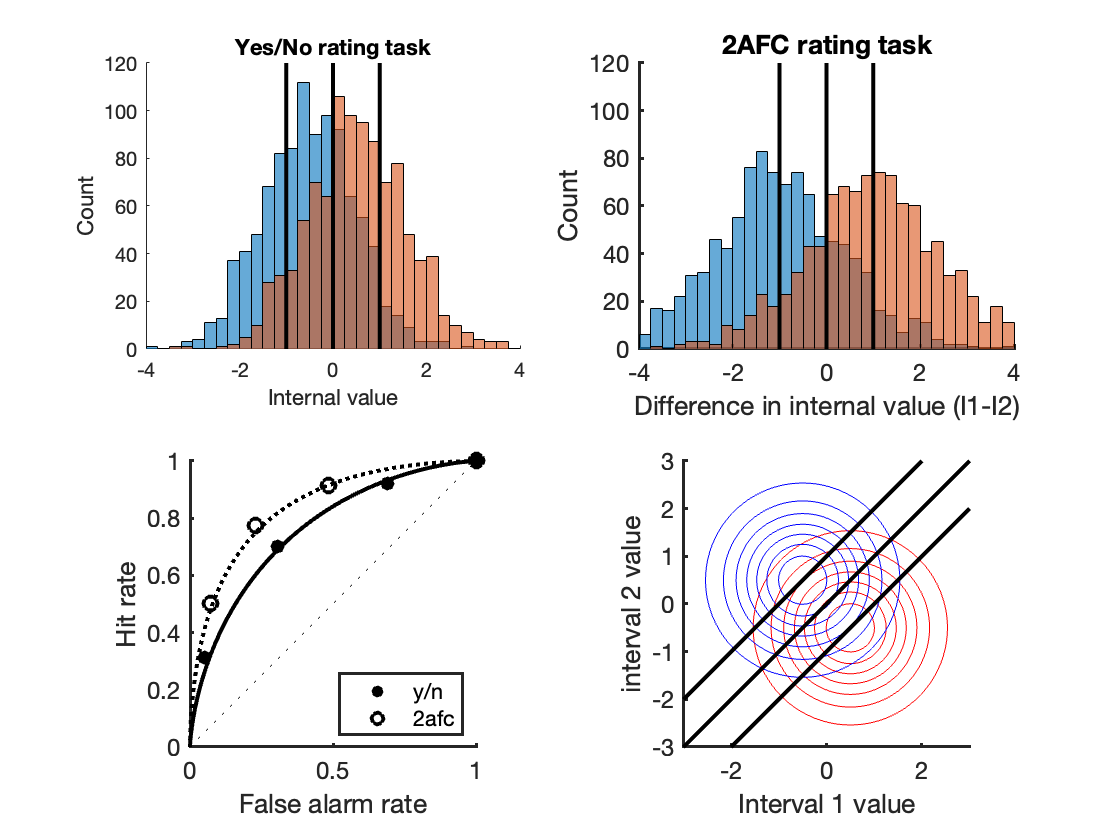

% to visualise the rating response

% 1. the yes/no task

% back to the distributions of observer 1
ntrials = 2000;
psignal = 0.5; % the proportion of signal-present trials

signal_strength = 1;

noise_mean = -0.5;
noise_sd = 1;

noise = (randn(ntrials,1)*noise_sd)+noise_mean;

noise_samps = noise(1:round(ntrials*(1-psignal))); 
% the first half of trials in this case
signal_samps = noise(round(ntrials*(1-psignal))+1:ntrials) + signal_strength; 
% we simply add the signal to the noise

ncriteria = 3; % the observer is asked for a rating on a 4 point scale
these_criteria = linspace(-1,1,ncriteria); 
% this gives us 4 equally spaced values from -1 to 1

% the observer gives a rating of 1 for anything that falls below the first
% criterion, a rating of 2 for anything between the first and the second
% criteria, a rating of 3 for anything between the second and third, and a
% rating of 4 for anything above the third criterion
responses = nan(ntrials/2,2); 
% for ease of calculation, I'm keeping signal and noise trials separate 
% in the first and second column
responses(noise_samps<these_criteria(1),1) = 1;
responses(signal_samps<these_criteria(1),2) = 1;
responses(logical((noise_samps>=these_criteria(1)).*(noise_samps<these_criteria(2))),1) = 2;
responses(logical((signal_samps>=these_criteria(1)).*(signal_samps<these_criteria(2))),2) = 2;
responses(logical((noise_samps>=these_criteria(2)).*(noise_samps<these_criteria(3))),1) = 3;
responses(logical((signal_samps>=these_criteria(2)).*(signal_samps<these_criteria(3))),2) = 3;
responses(noise_samps>=these_criteria(3),1) = 4;
responses(signal_samps>=these_criteria(3),2) = 4;

% pre-specify the variables
hit_rates = nan(ncriteria+1,1);
fa_rates = nan(ncriteria+1,1);

for ci = 1:(ncriteria+1)
    
    hit_rates(ci) = mean(responses(:,2)>=ci); 
    % here "mean" gives us the proportion, because inside the 
    % bracket will be an array of 0s and 1s
    fa_rates(ci) = mean(responses(:,1)>=ci);
end

% plot the visualisation of the criteria and the resulting ROC
figure;
subplot(2,2,1)
hold on
histogram(noise_samps,'BinWidth',0.25)
histogram(signal_samps,'BinWidth',0.25)
for ci = 1:3
    plot([these_criteria(ci),these_criteria(ci)],[0,120],'k','LineWidth',2)
end
axis([-4,4,0,120])
xlabel('Internal value')
ylabel('Count')
title('Yes/No rating task')

subplot(2,2,3)
hold on
scatter(fa_rates,hit_rates,50,'k','filled')
xlabel('False alarm rate')
ylabel('Hit rate')
axis square
makeMyPlotPretty

% 2. the forced choice task
% to visualise the forced choice task, I will first plot the theoretical
% distributions, and the criterion placement

% the criteria are essentially placed on the difference in the internal
% value between the intervals

% theoretical distributions - 2d gaussians

[xs,ys] = meshgrid(linspace(-4,4,100),linspace(-4,4,100)); 
% this gives us a grid of x and y coordinates
% the probability density is given by a multivariate normal function, which
% takes the x and y values, the two means, and the covariance matrix
% [x-sd,cov-xy;cov-xy,y-sd]
interval1pdf = mvnpdf([xs(:),ys(:)],[noise_mean+signal_strength,noise_mean],...
    [noise_sd,0;0,noise_sd]);
interval1pdf = reshape(interval1pdf,size(xs));
interval2pdf = mvnpdf([xs(:),ys(:)],[noise_mean,noise_mean+signal_strength],...
    [noise_sd,0;0,noise_sd]);
interval2pdf = reshape(interval2pdf,size(xs));

% plot
subplot(2,2,4)
hold on
[~,cobj1] = contour(xs,ys,interval1pdf,'r'); 
% 2D contour of the probability density - each line demarcates equiprobable values
[~,cobj2] = contour(xs,ys,interval2pdf,'b');

plot([-4,4],[-4,4],'k','LineWidth',2)
plot([-3,4],[-4,3],'k','LineWidth',2)
plot([-4,3],[-3,4],'k','LineWidth',2)
xlabel('Interval 1 value')
ylabel('interval 2 value')
axis([-3,3,-3,3])
axis square
makeMyPlotPretty

% the way the observer should respond is with a high rating when the
% interval 2 evidence is really much bigger than interval 2 (the difference
% is greater than some value) and vice versa

interval1_samps = ( randn(ntrials,1)*noise_sd ) + noise_mean;
interval2_samps = ( randn(ntrials,1)*noise_sd ) + noise_mean;

% half the time, interval 1 contains the signal, the other half, interval 2
% contains the signal

interval1_samps(1:(ntrials/2)) = interval1_samps(1:(ntrials/2)) + signal_strength;
interval2_samps((ntrials/2)+1:ntrials) = interval2_samps((ntrials/2)+1:ntrials) + ...
    signal_strength;

difference2 = interval1_samps(1:(ntrials/2)) - interval2_samps(1:(ntrials/2)); 
% keeping them separate for ease with code below
difference1 = interval1_samps((ntrials/2)+1:ntrials) - ...
    interval2_samps((ntrials/2)+1:ntrials);

% same deal as with the yes/no task
responses = nan(ntrials/2,2); 
% for ease of calculation, I'm keeping signal and noise trials 
% separate in the first and second column
responses(difference1<these_criteria(1),1) = 1;
responses(difference2<these_criteria(1),2) = 1;
responses(logical((difference1>=these_criteria(1)).*(difference1<these_criteria(2))),1) = 2;
responses(logical((difference2>=these_criteria(1)).*(difference2<these_criteria(2))),2) = 2;
responses(logical((difference1>=these_criteria(2)).*(difference1<these_criteria(3))),1) = 3;
responses(logical((difference2>=these_criteria(2)).*(difference2<these_criteria(3))),2) = 3;
responses(difference1>=these_criteria(3),1) = 4;
responses(difference2>=these_criteria(3),2) = 4;

% pre-specify the variables
hit_rates2afc = nan(ncriteria+1,1);
fa_rates2afc = nan(ncriteria+1,1);

for ci = 1:(ncriteria+1)
    
    hit_rates2afc(ci) = mean(responses(:,2)>=ci); 
    fa_rates2afc(ci) = mean(responses(:,1)>=ci);
end

% to visualise the responses
subplot(2,2,2)
hold on
histogram(difference1,'BinWidth',0.25)
histogram(difference2,'BinWidth',0.25)
for ci = 1:3
    plot([these_criteria(ci),these_criteria(ci)],[0,120],'k','LineWidth',2)
end
axis([-4,4,0,120])
xlabel('Difference in internal value (I1-I2)')
ylabel('Count')
title('2AFC rating task')
makeMyPlotPretty

subplot(2,2,3)
hold on
scatter(fa_rates2afc,hit_rates2afc,50,'ko','LineWidth',2)
plot([0,1],[0,1],'k:')
% the theoretical ROCs:
% yes/no
xs = linspace(-3,3,100);
hr = 1-normcdf(xs,noise_mean+signal_strength,noise_sd);
far = 1-normcdf(xs,noise_mean,noise_sd);
plot(far,hr,'k','LineWidth',2)
% 2afc
hr = 1-normcdf(xs,noise_mean+signal_strength,noise_sd/sqrt(2));
far = 1-normcdf(xs,noise_mean,noise_sd/sqrt(2));
plot(far,hr,'k','LineWidth',2,'LineStyle',':')
legend('y/n','2afc','location','southeast')
makeMyPlotPretty

The fact that these ratings resulted in different points on the ROC suggested *“Observers can discriminate among observations likely to result from noise alone” *Swets, Tanner, & Birdsall, (1961). That is, there are some false alarms ('yes' responses to signal-absent trials) that have a stronger perceived signal presence than others.

But another task really proved observers have this continuous experience and put the nail in the coffin for Threshold Theory (to tempt you into the optional extras below).

## Optional Extras

### **h. The second choice task**

The second choice task involves a 3AFC or 4AFC (or more) stimulus presentation design, but here the observer is asked to make two reports: a) which interval contains the signal; b) which is the next most likely interval to contain the signal (in case your first choice was incorrect - though the observer is asked for this response every trial irrespective of whether they were correct or incorrect).

SDT predicts that observers make errors when noise happens to excede the signal+noise. When performance is sufficiently high, it is unlikely that noise excedes signal+noise, it is even less likely that two noise intervals excede signal+noise. So, on trials where one interval of noise excedes the signal+noise, the signal+noise is more likely to be the next greatest internal value, and so performance on the second choice will be above chance. Threshold theory predicts that all errors are because the signal is below the threshold, and everything below the threshold is discrete absent, and so second choice performance will be at chance.

The simulation:

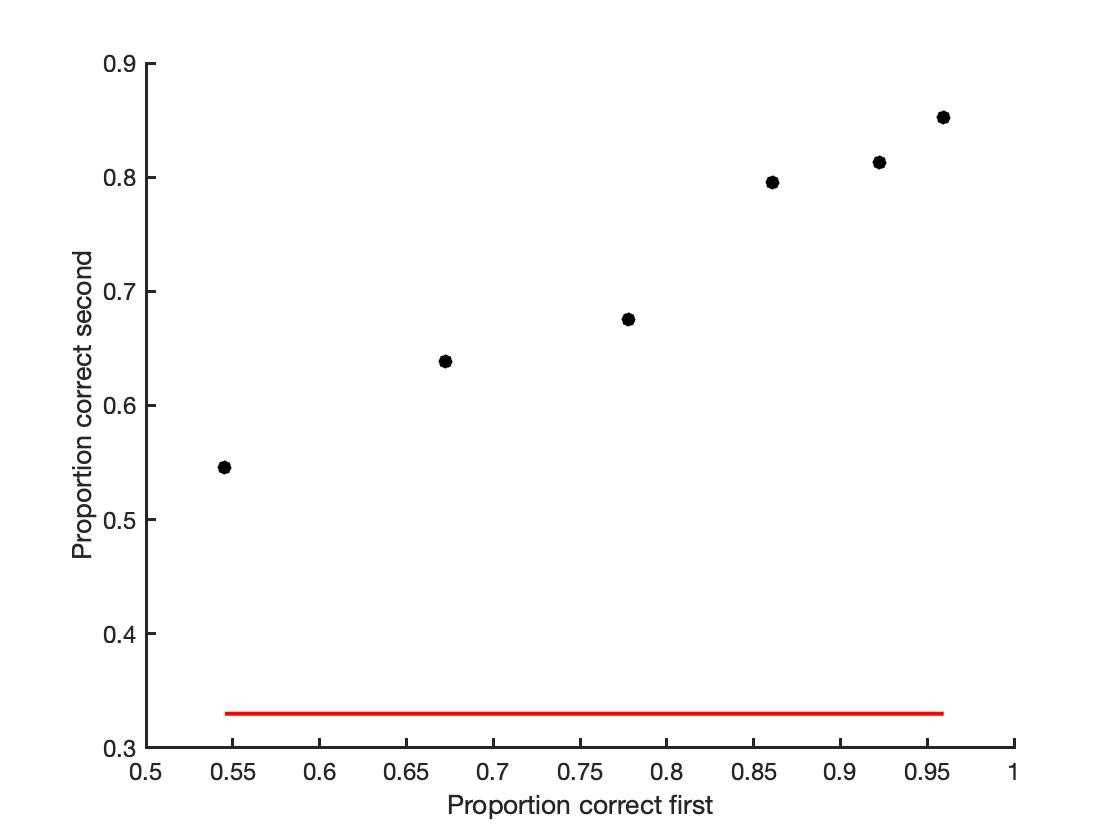


ntrials = 2000;
% general some noise
noise_samples = randn(ntrials,4); % for a 4AFC design

% simulate for different signal strengths
nsignals = 6;
signal_strength = linspace(1,3,nsignals);

proportion_correct_first = nan(nsignals,1);
proportion_correct_second = nan(nsignals,1);

for si = 1:length(signal_strength)
    
    this_signal = signal_strength(si);
    
    % for ease of computing, we put the signal always in interval 1
    % because of the way we simulate, it doesn't matter
    % in reality, we would put the signal equally across intervals 1 to 4
    
    this_evidence = noise_samples;
    this_evidence(:,1) = this_evidence(:,1) + this_signal;
    
    % which is the maximum in each interval?
    [~,response1] = max(this_evidence,[],2); 
    % this returns 1/2/3/4 for which or the four samples was greatest on each trial
    
    % to find the second best, turn the maximum to not a number
    inds = sub2ind([ntrials,4],[1:ntrials]',response1); 
    % this is to get the indexes of the maximum
    this_evidence(inds) = nan;
    
    [~,response2] = max(this_evidence,[],2);
    
    proportion_correct_first(si) = mean(response1==1);
    proportion_correct_second(si) = mean(response2(response1~=1)==1); 
    % only on incorrect trials
    
    
end

figure;
scatter(proportion_correct_first,proportion_correct_second,50,'k','filled')
hold on
plot(proportion_correct_first,ones(size(proportion_correct_first))*0.33,'r','LineWidth',2) 
% chance level, prediction for threshold theory 
xlabel('Proportion correct first')
ylabel('Proportion correct second')
makeMyPlotPretty

You can see that the prediction is well above the chance level predicted by Threshold Theory.

Actual human behaviour tends to be somewhere between the chance and what is predicted by SDT. One explanation of why can be found in Solomon (2007). This is an example of how SDT can be used as a normative description: here humans systematically underperform compared to the SDT prediction, so there must be more going on that isn't covered by SDT.

**KEY-KEY TAKE-AWAY: **To test different theories, we need different tasks, the ideal task is one where theories make very different predictions about behaviour. Even more ideally, we show our theory to predict different behaviour over multiple different tasks.

### i. The "assumption" of equal variance

Something that really annoys me is the assumption of the assumption of equal variance in SDT. The assumption is that SDT assumes that there is equal variance for the signal and noise distributions (the histograms plotted above have equal variance). It's true that this isn't discussed much, and the simple formulas given above don't leave room to account for unequal variance. But this is not a problem.

Here is the formula above:

d-prime = ( signal_mean - noise_mean ) / noise_sd 

Here is the formula to account for unequal variance:

d-prime = ( signal_mean - noise_mean ) / sqrt( noise_sd^2 + signal_sd^2)

The difference is comparable to a one-sample vs two-sample z-test.

The only problem with accounting for unequal variance is the willingness of the experimenter to measure it. To measure unequal variance, you have to measure a full ROC, this often means many more trials.

First, why might we hypothesise unequal variance?

Unequal variance can come from the 'multiplicative noise' (noise that increases with signal strength), for example, from the model of Lu and Dosher (1998). This is actually something we might predict from models of neural firing rates. Neural firing rates can be modelled with a poission distribution, where the variance increases with the mean (Jazayeri & Movshon, 2006; Seung, & Sompolinsky, 1993). If noise comes from baseline firing, and neurons respond to the signal with increased firing, and the variance increases with increasing mean, then the variance of the neural response to the signal will be greater than the noise (baseline).

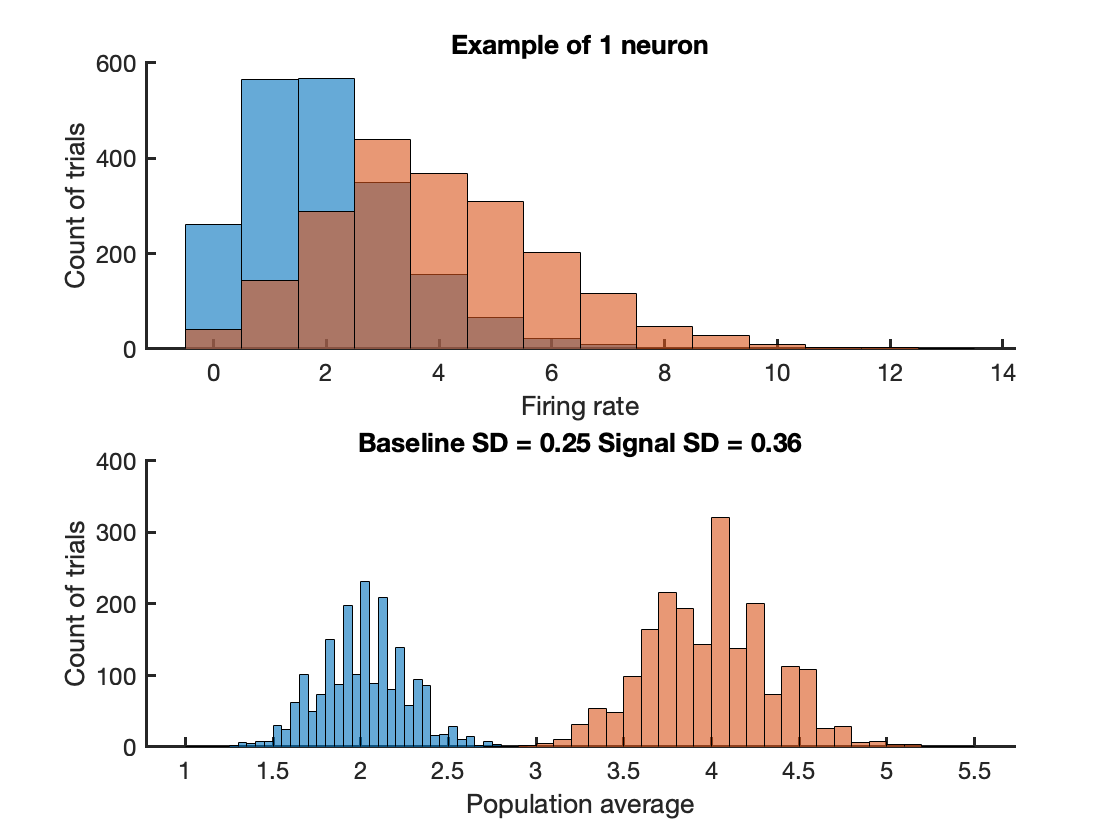

% some visualisation
% We sample firing rates from the 100 neurons over 1000 signal-absent trials
firing_rates_baseline = poissrnd(2,30,2000); % this function samples a poission distribution
% for signal-present trials, the firing rate increases
firing_rates_signal = poissrnd(4,30,2000);

% Let's say we read this out by taking the average firing rate as our
% estimate
est_absent = mean(firing_rates_baseline,1); % the average on the first dimension - across neurons
est_present = mean(firing_rates_signal,1);

% lets plot this
figure;
subplot(2,1,1)
hold on
histogram(firing_rates_baseline(1,:))
histogram(firing_rates_signal(1,:))
xlabel('Firing rate')
ylabel('Count of trials')
title('Example of 1 neuron')
makeMyPlotPretty

subplot(2,1,2)
hold on
histogram(est_absent)
histogram(est_present)
xlabel('Population average')
ylabel('Count of trials')

title(['Baseline SD = ' num2str(std(est_absent),2) ' Signal SD = ' num2str(std(est_present),2)])
makeMyPlotPretty

So multiplicative noise / unequal variance is neurobiologically plausible, especially in detection tasks.

Unequal variance is visible in ROCs

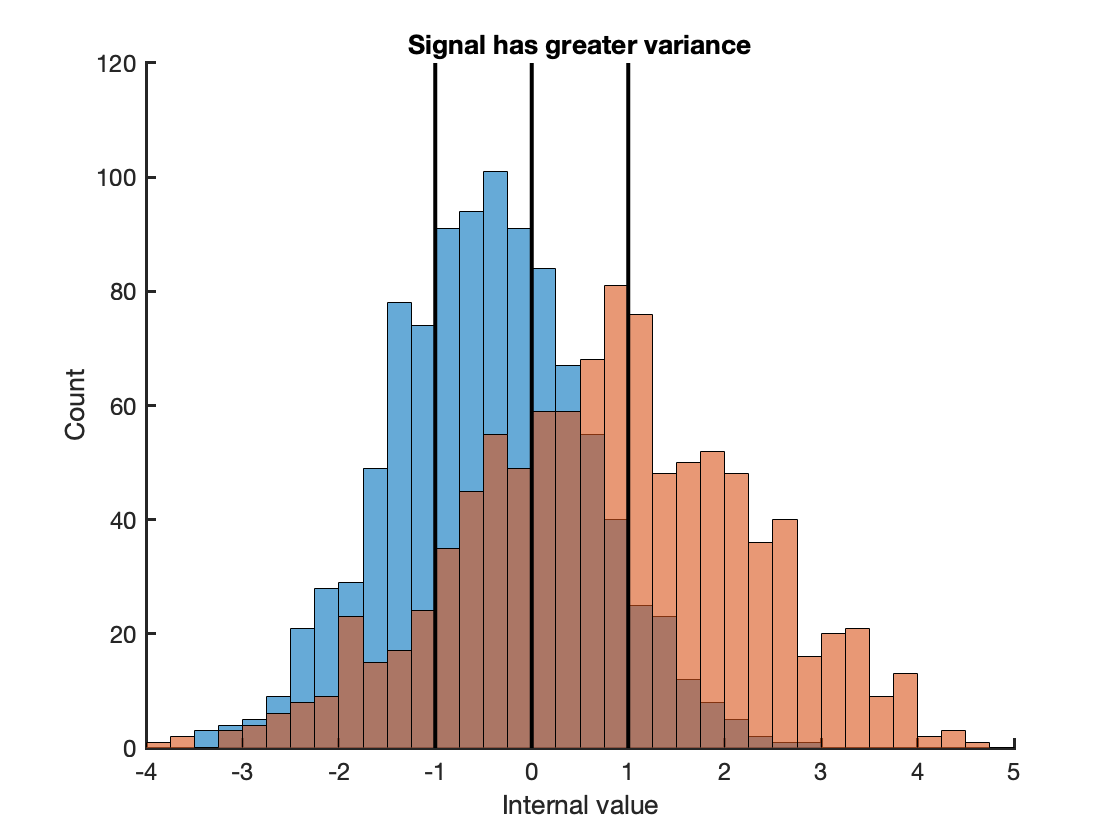

% back to our noisy observer in the rating task, but this time, the
% signal-present distribution has a higher varaince than the signal-absent
% distribution

ntrials = 2000;
psignal = 0.5; 

signal_mean = 0.75; % previously 0.5 - a bit stronger to account for the increased noise
signal_sd = 1.5;

noise_mean = -0.5;
noise_sd = 1;

noise_samps = (randn(round(ntrials*(1-psignal)),1)*noise_sd) + noise_mean;
signal_samps = (randn(round(ntrials*psignal),1)*signal_sd) + signal_mean;

ncriteria = 3; % the observer is asked for a rating on a 4 point scale
these_criteria = linspace(-1,1,ncriteria); 
% this gives us 4 equally spaced values from -1 to 1

% the observer gives a rating of 1 for anything that falls below the first
% criterion, a rating of 2 for anything between the first and the second
% criteria, a rating of 3 for anything between the second and third, and a
% rating of 4 for anything above the third criterion
responses = nan(ntrials/2,2); % for ease of calculation, I'm keeping signal and noise trials separate in the first and second column
responses(noise_samps<these_criteria(1),1) = 1;
responses(signal_samps<these_criteria(1),2) = 1;
responses(logical((noise_samps>=these_criteria(1)).*(noise_samps<these_criteria(2))),1) = 2;
responses(logical((signal_samps>=these_criteria(1)).*(signal_samps<these_criteria(2))),2) = 2;
responses(logical((noise_samps>=these_criteria(2)).*(noise_samps<these_criteria(3))),1) = 3;
responses(logical((signal_samps>=these_criteria(2)).*(signal_samps<these_criteria(3))),2) = 3;
responses(noise_samps>=these_criteria(3),1) = 4;
responses(signal_samps>=these_criteria(3),2) = 4;

% pre-specify the variables
hit_rates = nan(ncriteria+1,1);
fa_rates = nan(ncriteria+1,1);

for ci = 1:(ncriteria+1)
    
    hit_rates(ci) = mean(responses(:,2)>=ci); 
    % here "mean" gives us the proportion, because inside the 
    % bracket will be an array of 0s and 1s
    fa_rates(ci) = mean(responses(:,1)>=ci);
end

% plot the visualisation of the criteria and the resulting ROC
figure;
hold on
histogram(noise_samps,'BinWidth',0.25)
histogram(signal_samps,'BinWidth',0.25)
for ci = 1:3
    plot([these_criteria(ci),these_criteria(ci)],[0,120],'k','LineWidth',2)
end
axis([-4,5,0,120])
xlabel('Internal value')
ylabel('Count')
title('Signal has greater variance')
makeMyPlotPretty

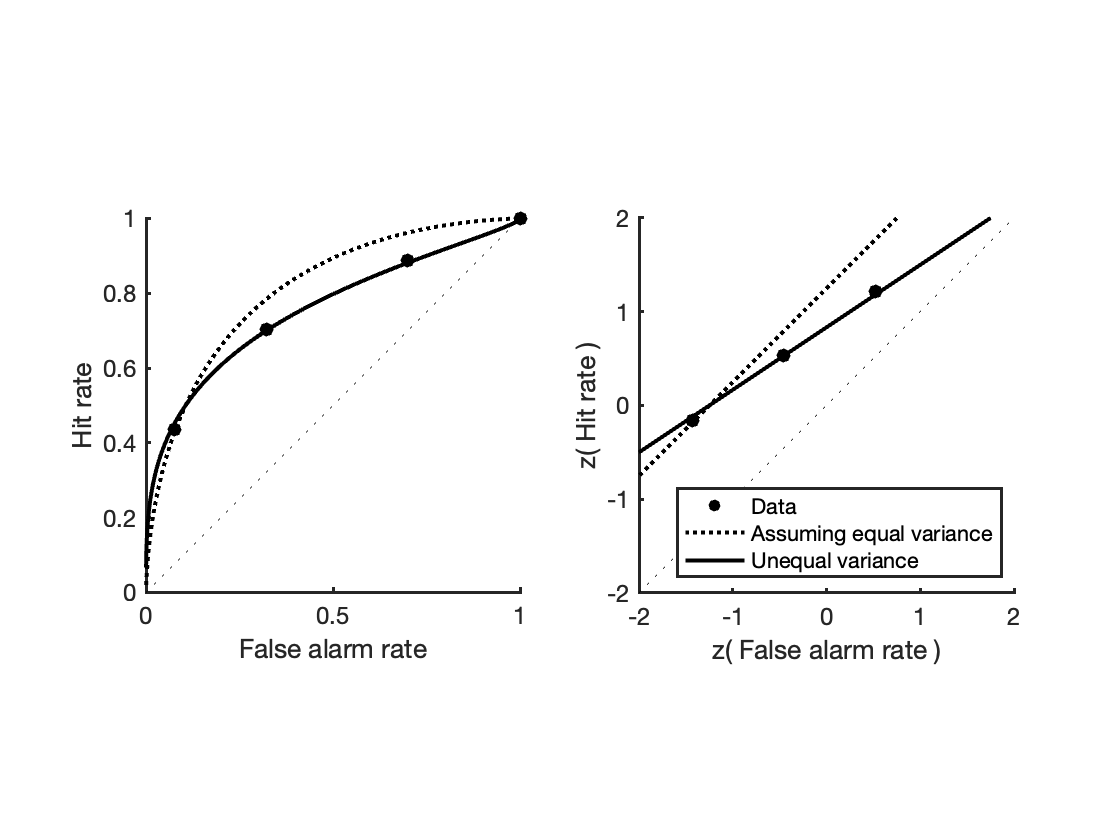


figure;
subplot(1,2,1)
hold on
scatter(fa_rates,hit_rates,50,'k','filled')

% the theoretical ROCs:
xs = linspace(-3,3,100);
% assuming equal variance
% hr = 1-normcdf(xs,signal_mean,sqrt((noise_sd^2)+(signal_sd^2)));
% far = 1-normcdf(xs,noise_mean,sqrt((noise_sd^2)+(signal_sd^2)));
hr = 1-normcdf(xs,signal_mean,noise_sd);
far = 1-normcdf(xs,noise_mean,noise_sd);
plot(far,hr,'k','LineWidth',2,'LineStyle',':')
% the true theoretical roc
hrc = 1-normcdf(xs,signal_mean,signal_sd);
farc = 1-normcdf(xs,noise_mean,noise_sd);
plot(farc,hrc,'k','LineWidth',2)

plot([0,1],[0,1],'k:')
xlabel('False alarm rate')
ylabel('Hit rate')
axis square
makeMyPlotPretty

% the inverse normal conversion
subplot(1,2,2)
hold on
scatter(norminv(fa_rates),norminv(hit_rates),50,'k','filled')
plot(norminv(far),norminv(hr),'k','LineWidth',2,'LineStyle',':')
plot(norminv(farc),norminv(hrc),'k','LineWidth',2)
plot([-2,2],[-2,2],'k:')
xlabel('z( False alarm rate )')
ylabel('z( Hit rate )')
axis([-2,2,-2,2])
axis square
legend('Data','Assuming equal variance','Unequal variance','location','southeast')
makeMyPlotPretty

Equal variance predicts a symmetric ROC, when the inverse normal of the hit and false alarm rates are plotted (on the right), this predicts a straight line parallel to the diagonal. Unequal variance is visible from the asymmetry on the left, and the non-uniform slope on the right.

**TAKE-AWAY: **Equal variance is not an assumption of SDT. You can detect and account for unequal variance by plotting ROCs

## Functions

function makeMyPlotPretty()

ax = gca;
ax.FontSize = 12;
ax.LineWidth=1.5;

end

### References

Albrecht, D. G., & Hamilton, D. B. (1982). Striate cortex of monkey and cat: contrast response function. *Journal of neurophysiology*, *48*(1), 217-237.

Blackwell, H. R. (1953). Psychophysical thresholds: Experimental studies of methods measurement. *Bull. Eng. Res. Inst. Univ. Mich.*, *36*.

Galvin, S. J., Podd, J. V., Drga, V., & Whitmore, J. (2003). Type 2 tasks in the theory of signal detectability: Discrimination between correct and incorrect decisions. *Psychonomic bulletin & review*, *10*, 843-876.

Hecht, S., Shlaer, S., & Pirenne, M. H. (1942). Energy, quanta, and vision. *The Journal of general physiology*, *25*(6), 819-840.

Jazayeri, M., & Movshon, J. A. (2006). Optimal representation of sensory information by neural populations. *Nature neuroscience*, *9*(5), 690-696.

Krantz, D. H. (1969). Threshold theories of signal detection. *Psychological review*, *76*(3), 308.

Lu, Z. L., & Dosher, B. A. (1998). External noise distinguishes attention mechanisms. *Vision research*, *38*(9), 1183-1198.

Luce, R. D. (1963). A threshold theory for simple detection experiments. *Psychological review*, *70*(1), 61.

Niemeyer, J. E., & Paradiso, M. A. (2017). Contrast sensitivity, V1 neural activity, and natural vision. *Journal of neurophysiology*, *117*(2), 492-508.

Seung, H. S., & Sompolinsky, H. (1993). Simple models for reading neuronal population codes. *Proceedings of the national academy of sciences*, *90*(22), 10749-10753.

Solomon, J. A. (2007). Intrinsic uncertainty explains second responses. *Spatial Vision*, *20*(1), 45-60.

Swets, J. A., Tanner Jr, W. P., & Birdsall, T. G. (1961). Decision processes in perception. *Psychological review*, *68*(5), 301.

Thurstone, L. L. (1927a). The method of paired comparisons for social values. *The Journal of Abnormal and Social Psychology*, *21*(4), 384.

Thurstone, L. L. (1927b). A law of comparative judgments. *Psychological Review, 34,* 273–286. 

Tinsley, J., Molodtsov, M., Prevedel, R. *et al.* (2016) Direct detection of a single photon by humans. *Nat Commun* **7**, 12172. 

Wald, A. (1949). Statistical decision functions. *The Annals of Mathematical Statistics*, 165-205.